# 第六次实验

clc

## 实验13-2（1）

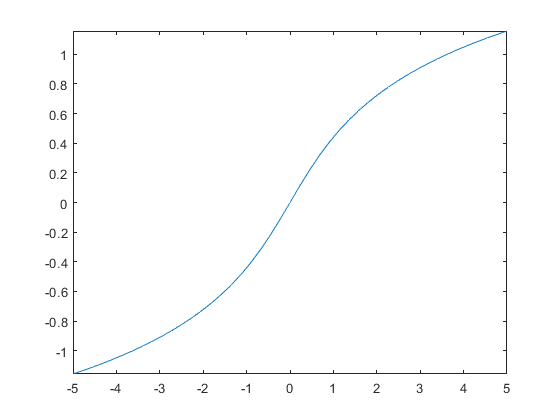

% 函数曲线定义
y = @(x) 1/2 * log(x+sqrt(1+x.^2));
% 曲线绘制
p = fplot(y);

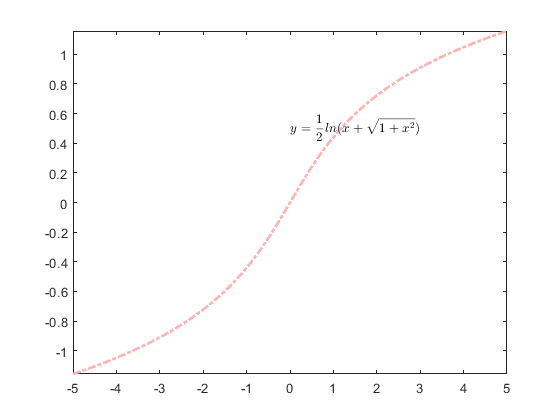

q = fplot(y);
% 改颜色
q.Color = [1 0.7 0.7];
% 改线型
q.LineStyle = '-.';
% 改线宽
q.LineWidth = 2;
% 加文字
text('Interpreter', 'latex','String', '$$y=\frac{1}{2}ln(x+\sqrt{1+x^2})$$', 'Position',[0 0.5]);

## 实验14-1

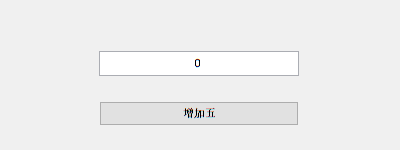

clear
% 设定窗口大小
fig = figure('Position',[20 20 400 150]);
% 设定初值
var = 0;
% 定义按钮功能
buttonFunction = 'var = str2num(get(edit, ''String'')) + 5; set(edit, ''String'', num2str(var))';
% 定义按钮样式
uicontrol(gcf, 'Style','pushbutton', 'String', '增加五', 'Callback',buttonFunction, 'Position', [100 25 200 25]);
% 定义对话框样式
edit = uicontrol('Style',"edit", 'String',num2str(var), 'Position', [100 75 200 25]);

## 实验 14-5

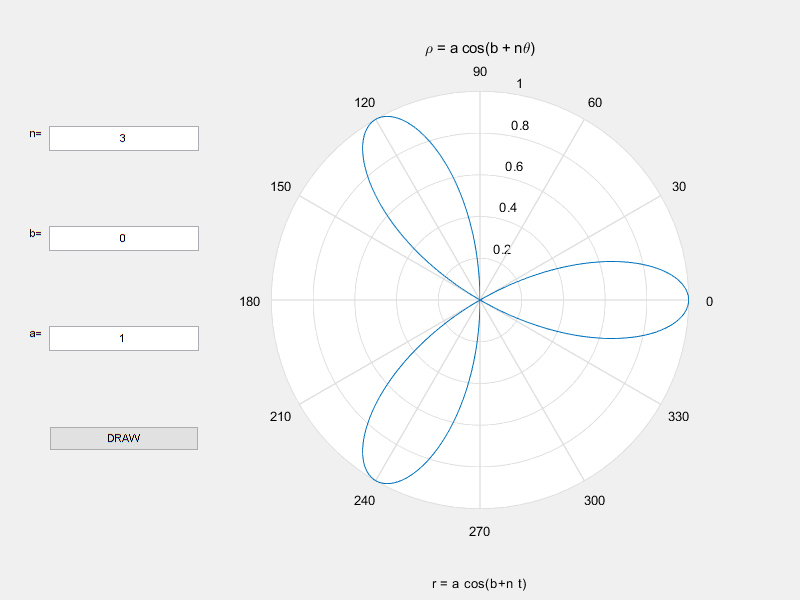

clear;
% 设定窗口大小
fig = figure('Position',[200 200 800 600]);
a = 1;
b = 0;
n = 3;
% 曲线定义
curve = @(t) a.*cos(b+n*t);
% 输入框定义
edita = uicontrol('Style',"edit", 'String',num2str(a), 'Position', [50 250 150 25]);
editb = uicontrol('Style',"edit", 'String',num2str(b), 'Position', [50 350 150 25]);
editn = uicontrol('Style',"edit", 'String',num2str(n), 'Position', [50 450 150 25]);
texta = uicontrol("Style","text", "String", 'a=', "Position", [25 250 25 25]);
textb = uicontrol("Style","text", "String", 'b=', "Position", [25 350 25 25]);
textn = uicontrol("Style","text", "String", 'n=', "Position", [25 450 25 25]);
% 按钮绘图功能
buttonFunction = ['a = str2num(get(edita, ''String'')); ' ...
    'b = str2num(get(editb, ''String''));' ...
    'n = str2num(get(editn, ''String''));' ...
    'curve = @(t) a.*cos(b+n*t); ezpolar(ax, curve);' ...
    'title("\rho = a cos(b + n\theta)");'];
% 按钮样式定义
button = uicontrol(gcf, 'Style','pushbutton', 'String', 'DRAW', ...
    'Callback',buttonFunction, 'Position', [50 150 150 25]);
% 绘制初始图象
ax = axes('Position',[0.3 0.1 0.6 0.8]);
ezpolar(curve);
title('\rho = a cos(b + n\theta)');

## P276 三 2

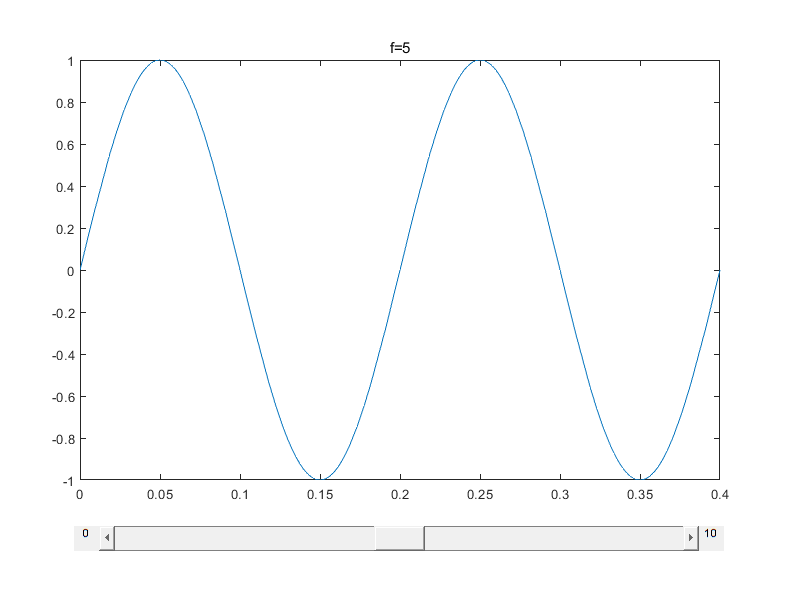

clear;
% 设定初始频率和初始正弦曲线
f = 5;
w = 2*pi*f;
curve = @(x) sin(w*x);
% 定义窗口大小
fig = figure('Position',[200 200 800 600]);
% 绘制初始曲线
ax = axes('Position',[0.1 0.2 0.8 0.7]);
p = fplot(ax, curve, [0, 4*pi/w]);
title(['f=' num2str(f)]);
% 定义滚动条功能
sliderCallBack = ['f = get(slider, ''Value''); w = 2*pi*f; ' ...
    'curve = @(x) sin(w*x); fplot(ax, curve, [0, 4*pi/w]);' ...
    'title([''f='' num2str(f)]);'];
% 定义滚动条数值
slider = uicontrol(gcf, "Style","slider","Position",[100 50 600 25], 'Min',eps,'Max',10, ...
    'Value', f, 'Callback', sliderCallBack);
text0 = uicontrol("Style","text", "String", '0', "Position", [75 50 25 25]);
text10 = uicontrol("Style","text", "String", '10', "Position", [700 50 25 25]);

## P276 三 3

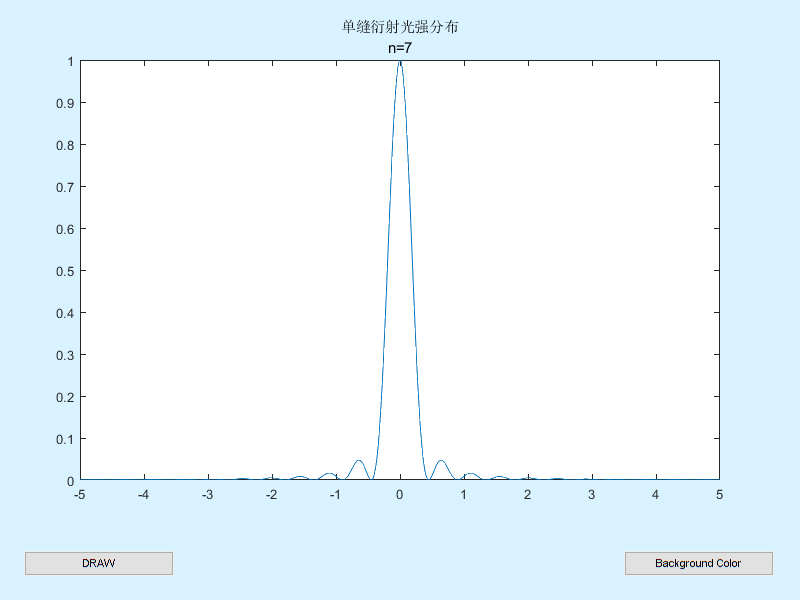

clear;
% 定义窗体大小
fig = figure('Position',[200 200 800 600]);
% 定义初始曲线
n = fix(1+rand()*10);
curve = @(x) (sin(n.*x)./n./x).^2;
% 绘制初始曲线
ax = axes('Position',[0.1 0.2 0.8 0.7]);
fplot(ax, curve, [-5 5]);
strinfo = strcat("n=",num2str(n));
title(["单缝衍射光强分布" strinfo]);

% 指定初始背景色（天蓝色）
set(gcf, "Color", [0.85 0.95 1]);

% 指定绘制曲线的按钮功能
buttonFunction = ['n = fix(1+rand()*10); ' ...
    'curve = @(x) (sin(n.*x)./n./x).^2; fplot(ax, curve, [-5 5]);' ...
    'strinfo = strcat("n=",num2str(n));'...
    'title(["单缝衍射光强分布" strinfo]);'];
% 定义绘制曲线的按钮样式
button = uicontrol(gcf, 'Style','pushbutton', 'String', 'DRAW', ...
    'Callback',buttonFunction, 'Position', [25 25 150 25]);
% 指定更换背景色的按钮功能
button2Function = 'set(gcf, "Color", [rand rand rand])';
% 定义更换背景色的按钮样式
button2 = uicontrol(gcf, 'Style','pushbutton', 'String', 'Background Color', ...
    'Callback',button2Function, 'Position', [625 25 150 25]);